# Tutorial on using Human-microbiome models

## Solving Models

Bram Nap, Tim Hensen, Anna Sheehy - 07-2024

This tutorial will explain step by step different ways of setting objective functions, solving human-microbiome models (mWBMs) and code to efficiently optimise multiple reactions for all models and how to perfrom different analsyes on the resulting flux data. The princinples explained here are also valid for whole body models (WBMs), personalised WBMs (iWBMs) and microbiome, personalised WBMs (miWBMs).

We will make sure the COBRA toolbox is initialised and the appropriate solver is set. The different solvers supported are

- cplex_direct

- gurobi

- ibm_cplex

- mosek

- tomlab_cplex

To change the solver, put the solver name of the list above in place of ibm_cplex in the code below. To see MATLAB version and solver version compatibility see [https://opencobra.github.io/cobratoolbox/stable/installation.html#solver-installation](https://opencobra.github.io/cobratoolbox/stable/installation.html#solver-installation)

Various solvers can be obtained through an free academic license.

global CBTDIR
if isempty(CBTDIR)
    initCobraToolbox
end

% Define and set the solver. The names defined in the bullet points above
% are the names accepted in the changeCobraSolver function. To switch
% solver just change ibm_cplex to the solver of your choice.
solver = 'ibm_cplex';

changeCobraSolver(solver);

For ease of access we will again define the folders used to store and read results from. If tutorial 1 and 2 are used, please use the same inputs used in those tutorials. If you downloaded the pre-made tutorial files set the path for the downloaded files as the resultPath variable. We will also define the metadata path again as we will need it later in this tutorial. Note that the explanation and steps are the exact same for the setup as in the other tutorials. If the directories already exist - the code will recognise that and not make a new one and will not overwrite the data inside of it.

- resultPath - The path where all the results of this tutorial will be stored. This ensure all your results will be in one place and are thus easily accesible. Make sure the the folder is accesible to you.

- **metadataPath** - The location of the metadata file. This is used in both the generation of human-microbiome models as well as the analysis of results towards the end of the tutorial.

- **readsTablePath** - The path to the the taxonomic reads file containing the amount of reads per taxonomic assignment. Here we will set to it to an empty string as we do not need it ('')

We set up the variables in the **paths** variable, which is a structure. Each field in the structure is dedicated to store the relevant variables used in the different steps of Persephone. Normally we would define each variable at the start in the configuration file. However here we will only specifiy the output directories used in Persephone. The other variables we will define as we go along for clarity.

Please copy and paste the paths to the required files in the code below. Remember to add file extensions where relevant.

% Define the location of the required files, make sure you don't 
% forget the file extensions where relevant!
resultPath = '';

paths.General.metadataPath = '';

% Leave as an empty string!
paths.Mars.readsTablePath = ''

Now we will define some paths as to where we want to store all of our results. We do not have to make these directories ourselves, the code will do it for us.

paths.seqC.outputPathSeqC = [resultPath, filesep, 'resultSeqC'];
paths.Mars.outputPathMars = [resultPath, filesep, 'resultMars'];
paths.mgPipe.outputPathMgPipe = [resultPath, filesep, 'resultMgPipe'];
paths.persWBM.outputPathPersonalisation = [resultPath, filesep, 'personalisedWBMs'];
paths.mWBM.outputPathMWBM = [resultPath, filesep, 'mWBMmodels'];
paths.fba.outputPathFluxResult = [resultPath, filesep, 'resultFlux'];
paths.fba.outputPathFluxAnalysis = [paths.fba.outputPathFluxResult, filesep, 'fluxAnalysis'];
paths.stats.outputPathStatistics = [resultPath, filesep, 'resultStatistics'];


The function *initPersephone.m* performs the *initCobraToolbox.m* function, sets the COBRA solver and checks if the required toolboxes are installed (line 1-7). Additionaly it generates the folder structure for the results. IMPORTANT, the output structure used in all 3 tutorials is generated with initPersephone.m. The metadata and the reads table are put through sanity checks. initPersphpne.m ensures that in the metdata the columns with the sample IDs and sample sex have the correct headers and readable data types. It always assumed the first column contains sample IDs. It will create a new updated file and will also update the metadata path accordingly. If you use the test data files you can see that the column sample ID has been changed to ID and the column gender has been altered to Sex. Additionally the data in the column Sex has been changed from M/F to male/female. Important if your own metadata does not have alternative headers accounted for in the function it will raise ahnerror. That is easily fixed by changing your column headers to ID or Sex depending on which data type is causing the issue. Finally we test if the sample IDs in the microbiome data match that of the metadata.

% Create the file structure for the results of all the parts of the
% tutorial (not just this tutorial)
[initialised, statToolboxInstalled, updatedMetadataPath] = initPersephone(resultPath, paths)

The following ouputs are returned from initPersephone

- **initialised -** Boolean, indicates if Persephone was succesfully initialised.

- **statToolboxInstalled -** Boolean, indicates if the statistics toolbox is installed. Parts of Persephone are skipped if false

- **updatedMetdataPath**  -  The path to the updated metadata file.

If you look at the directory given in the resultPath variable, you will see the following folder structure.

-resultPath

    -HMmodels

    -personalisedWBMs 

    -resultFlux

        -fluxAnalysis

    -resultMars

    -resultMgPipe

    -resultSeqC

    -resultStatistics

The content of each of the folders will be discussed in the appropriate sections in the three tutorials.

We have to also update the metadata path to reflect the updated metadata file.

paths.General.metadataPath = updatedMetadataPath;

### Part 1: Prepare WBM model for analysis. 

The first step before we can begin solving an mWBM, is making sure that the appropriate constraints are set. First we have to load a mWBM, we will use model **mWBM_CSM5MCXD.mat** created from the test dataset in **Tut_1_0_MicrobiomeCreation. **If the tutorial is followed it should be stored in the folder mWBMmodels. The model can also be found in the supplementary materials.

% Indicate the path to the mWBMs as created in the previous tutorial 
% OR use download the mWBM models from the supplementary 
% files from the paper and load the model
pathToModel = which('mWBM_CSM5MCXD_female.mat'); 
% Make sure that mWBM_CSM5MCXD is 
% stored in a folder that is added to the Matlab path

model = loadPSCMfile(pathToModel);

If you get an error here, you may need to check that the mWBMmodels folder is on your matlab path. You can do this by right clicking on the folder and selecting 'Add to path' and then selecting 'Selected Folders and Subfolders'.

% The model should be in the defined directory if resultPath indeed
% contains the mWBMmodels folder and the CSM5MCXD.mat file. If not you can set
% the path directly by entering the full path and the file name and
% extensions within the load() function. Ensure quotation marks '' around
% the path name.
mWBM = load([paths.mWBM.outputPathMWBM, filesep, 'mWBM_CSM5MCXD_female.mat']);

#### Set "Whole_body_objective_rxn" flux bounds

The '`Whole_body_objective_rxn'` is an artificial reaction that represents the **total biomass being produced **in the body. This reaction includes dummy duplicates of all organ biomass metabolites that are coupled to the organ biomass reactions. The dummy biomass metabolite stoichiometries are scaled by a coefficient corresponding to their relative organ weight. Thus, each organ's contribution to the whole-body biomass production is weighted according to its size or mass relative to the entire body. By default the constraints on this reaction are set to [1,1] mmol/day, which represents a 100% biomass production and maintenance throughout the body but it always good practice to reset in case of doubt. We set the bounds to [1,1] mmol/day to make sure we can compare different models with each other and that differences are not caused by changes in flux through the "Whole_body_objective_rxn". It is recommended keep the bounds to [1,1] mmol/day as that is an optimised value for modelling and changing can lead to unexpected flux values or errors. To change reaction bounds we use the changeRxnBounds function. changeRxnBounds changes the constraints on the upper and/or lower bounds of a specified reaction or set of reactions in the model and takes the following inputs:

- **model** - A metabolic model, in our case a mWBM or WBM

- **rxnNameList** - A cell array of reactions that have to have their bounds changed.A cell array of reaction IDs or a string for a single reaction ID that species which reaction(s) need their bounds altered. In our case 'Whole_body_objective_rxn'

- **value** - A numeric value that say to which value the bound has to be changed to. Can be one value for all reactions, or one value for each reaction to be changed. In our case the value 1.

- **boundType** - A string, indicating which bound has to be changed, u= upper, l= lower, b = both. In our case 'b' as we want both bounds to have the same value.

% Change the reaction bounds 
mWBM = changeRxnBounds(mWBM, 'Whole_body_objective_rxn', 1, 'b');

To check if the changes were succesful we can use the function printFluxBounds which takes:

- **model** - A metabolic model, in our case a mWBM or WBM

- **rxns** - Cell array of reactions in the model to print the bounds for. In our case "whole_body_objective_rxn"

- **rxnNameFlag **- determines if scientific notation for numbers is used. 1 is for scientific, 0 is normal notation

% Display the flux bounds on the objective reaction
printFluxBounds(mWBM,{'Whole_body_objective_rxn'}, 0)

To understand the  '`Whole_body_objective_rxn', `it's helpful to understand how biomass reactions work. There are 3 types of biomass reaction in the WBMs: 

***biomass_reaction:*** 

for organs with regenerative capacity

***biomass_maintenance:*** 

accounts for maintaining the cellular metabolic profile without including nuclear deoxynucleotides

***biomass_maintenance_noTrTr:*** 

(no translation, no transcription) This reaction is used excludes amino acids, nuclear deoxynucleotides, and cellular deoxynucleotides except for adenosine-triphosphate (ATP). It can be used to mimic fasting conditions in the models. Let's take a look at all the biomass reactions in the model:

To find the reactions associated with biomass in the mWBMs we

- Obtain the indexes (idx in the code) of the reaction IDs that contain the word "biomass"

- Print the reaction IDs associated with the indices

% Find reactions containing 'biomass'
biomassReactions = model.rxns(contains(model.rxns, 'biomass'))

You can see the different biomass reactions in the biomassReactions that make up the complete whole body biomass reaction, as well as the biomass reactions that produce the biomass for the pan-species models. These, however, are only used in the biomass reaction for the community microbiome biomass.

Organs which have regerative capacities (e.g., liver, heart, and kidney) will have their specific '`biomass_reaction'` included in the '`Whole_body_objective_rxn'`. Other organs will use the '`biomass_maintenance'` reaction.(For more detail see: [https://pubmed.ncbi.nlm.nih.gov/32463598/).](https://pubmed.ncbi.nlm.nih.gov/32463598/).) The '`Whole_body_objective_rxn'` thus provides a comprehensive representation of the body's overall biomass production, taking into account the unique metabolic requirements and contributions of each organ.

% Print the reaction formula
wbmReaction = printRxnFormula(mWBM, 'Whole_body_objective_rxn');

## Look at dietary input

When analysing multiple WBM models, it is important that the models have an identical dietary input as otherwise we will not know if changes in flux results originate from the personalisations/microbiome or from the diet. Therefore we ensure here that the models have identical diets. We constrained the HM models in tutorial 1 or 1.5 with the EUAverageDiet. Setting the diet automatically introduces a range up and downwards on the given value to be set as a bound as we can see with the dietary bound on D-glucose. Dietary reactions always follow the structure Diet_EX_"metabolite ID"[d].

% Print flux bound of D-glucose in the diet
printFluxBounds(mWBM, {'Diet_EX_glc_D[d]'}, 0)

Models might take up different amounts of glucose, however if we fix the dietary uptake to a single value, all the unused glucose will be automatically excreted in the feces. In the end it does not matter if we have a range between the lower and upper bound or a single value for both, as long as all the models have the same bounds.

## **Fixing community microbiome biomass production**

When investigating microbial influences on host metabolism, the total biomass flux between the host and the microbiome is commonly fixed at one.

**Why set the biomass production?**

- **Consistency in Metabolite Flow: **Fixing the flux ensures that the flow of metabolites between the host and microbiome is constant. This means that even if the microbiome's composition changes, the total amount of metabolites exchanged remains the same. This setup mimics a steady-state interaction where the host and microbiome are in a balanced metabolic exchange.

- **Comparability of Flux Values: **By maintaining a fixed biomas flux, the flux values in specific reactions become more comparable across different microbiome compositions. This is because the fluxes now represent relative changes in the microbiome structure rather than absolute differences in metabolite amounts. It allows the investigator to focus on how the microbiome's structure affects metabolic exchanges rather than being confounded by varying total metabolite amounts.

To change to reaction bounds of the microbiome biomass production we use the same function as before, changeRxnBounds.

% Change the reaction bounds
mWBM = changeRxnBounds(mWBM, 'Excretion_EX_microbiota_LI_biomass[fe]', 1, 'b');

## Part 2: Flux analysis based on various types of objective reactions

Choosing the right objective reaction is a matter of biological interest and is dependent on:  

- Which reaction/metabolite is of interest

- Which organ/s are most relevant

- Availability of omics data, e.g., serum and urine metabolomics

As outlined in Thiele *et al.* (2020) [1] whole body models we are working with capture metabolism in 26 organs, some of which can are outlined in the diagram below. The models 'blood compartment', constrained by realistic parameters based of blood flow rate and metabolite concentration, is the connection compartment which allows for exchange of metabolites between compartments where each has unique lower and upper bounds on the specific metabolites in question.

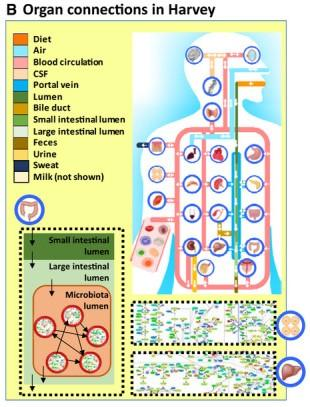

*A schematic overview of the construction of the WBMs with the left bottom showing the microbiome intergration. Taken and adapted from [1]*

This allows us to explore organ specific metabolism and it means that when we caculate the flux of a metabolite in downstream organs e.g. bladder, colon etc.,  Not only does the model take into account the organ where the flux is calculated but the all the organs which might contribute the metabolite availability in that particular organ giving us more accurate predictions. When dealing with model comaprtments that represent blood, urine, faeces or cereoborspinal fluid (CSF) it also means that where metabolomic data is available, we can compare it to the models prediction.

Reactions typically follow a specific naming format. Reactions within organs defined by their reactions ID and the organ in which they are happening (this may be a human organ or microbe). For example,this hyptotaurine/taurine oxireductase reaction (r0381) can be found in the VMH as:

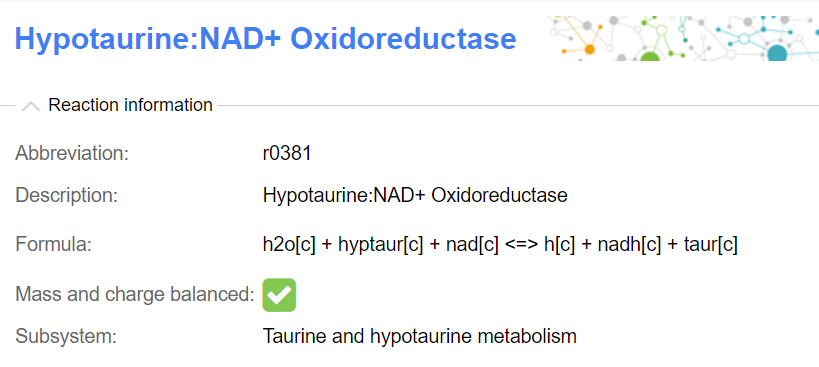

and can be found in the model in these (and other organs/cells/microbes) written as follows:

**Colon_r0381**

**RBC_r0381**

**panMorganella_morganii_r0381**

Exchange reactions  are mass-inbalanced and can give valuable insights into the amount of metabolites exchanged with the environment. The naming of reactions in the models follows a pattern so all excretion reactions contain 'EX_'  and ends in the biofluid comparment that has has interactions witht the environment ([u], [fe], [a], [sw], [d]) For example: Exchange of D-Glucose from metabolite pools uring, blood and CSF would be written as follows: 

**EX_glc_D[u]**

**EX_glc_D[fe]**

**EX_glc_D[d] **

Transport reactions are mass-balanced and transport metabolites from one compartment to another :

**glc_D[e]   <=>   glc_D[c] **

The typical naming convention is either a lower case t in the reaction name (which is usually all upper case) or it will indicate two compartment names in the reaction ID. Examples are shown for the transport of 2-oxo-butyrate from the lumen to the diet and the transport of cholate from the liver cytosol to the portal vein. Most transport reactions are reversible.

**GI_EX_2obut[lu]_[d]**

**Liver_CHOLATEt[bpL]**

## Solving for existing reactions in the model

We will now go through various examples to set the objective function to existing reactions and solve the models.

### Example One: Urinary reaction

If you are interested in L-tryptophan excretion fluxes in the urine, you can investigate the metabolite following these steps: 

-  Find the Virtual Metabolic Human(VMH) ID for L-tryptophan here: [https://vmh.life/](https://vmh.life/)

- Check if the model contains that metabolite in the urinary compartment using the surfNet function. This will also give you the a list of the 'consuming' and 'producing' reactions in the model for that metabolite.

surfNet(mWBM, 'EX_trp_L[u]')

Now you can construct the reaction name using the format seen above. *careful with the spelling, underscores and brackets! Use the 'changeObjective' function to set urinary excretion of L-tryptophan as the model objective:

% Update objective reaction
mWBM = changeObjective(mWBM, 'EX_trp_L[u]');

Set the models sense to maximise for the objective:

% Set objective function to maximise for the reaction
mWBM.osenseStr = 'max';

Optimize and display the flux value (solution.f)

% Perform FBA
solution = optimizeWBModel(mWBM);
% The "f" field in the FBA variable contains the maximised flux
solution.f

When model muWBM_CSM5MCXD_female.mat is solved for EX_trp_L[u] (urinary excretion of L-tryptophan) we see that the maximum flux value is 0.0062 mmol/day. Interesting is if we look at the bounds printed when we called the surfNet function is the the maximum allowed excretion value is only 0.000038 mmol/day highter than our optimised value. This means we are close to the maximum allowed flux value allowed by the model. It is thus alway good to check the bounds of a reaction you want to optimise if you obtain multiple duplicate values for different models.

### Example Two: Faecal excretion reactions

We can perform the same technique if we e.g., want to look at the exchange of L-proline in the faeces. Important that for faecal exchange reactions, 'Excretion' has to be added in front of the expected exchange reaction ID. First we need to check if the reaction exists in the model:

% Check if the reactions exists
surfNet(mWBM, 'Excretion_EX_pro_L[fe]')

We see that the bounds on the excretion reaction are [0, 1000000]. Now we perform FBA as shown in example one.

% Update objective reaction
mWBM = changeObjective(mWBM, 'Excretion_EX_pro_L[fe]');
% Set objective function to maximise for the reaction
mWBM.osenseStr = 'max';
% Perform FBA
solution = optimizeWBModel(mWBM);
% Print the "f" field in the FBA variable
solution.f

Using model HM_CSM5MCXD we see that the maximum exchange of feacal L-proline is 239.5559 mmol/day.

### Example Three: Reactions in a particular organ

We can also solve reactions performing metabolic transformation in specific organs. Lets take the oxireductase reaction we mentioned earlier involving taurine and hypotaurine in the liver.

Check if the reaction exists

surfNet(mWBM, 'Liver_r0381')

We see that is an unbound reaction that is reversible. To solve the model for this reaction we follow the steps outlined in example 1:

% Update objective reaction
mWBM = changeObjective(mWBM, 'Liver_r0381');
% Set objective function to maximise for the reaction
mWBM.osenseStr = 'max';
% Perform FBA
solution = optimizeWBModel(mWBM);
% Print the "f" field in the FBA variable
solution.f

For model HM_CSM5MCXD we see that reaction r0381 has a maximum value of 384.9729 mmol/day in the liver. If we would to do this for multiple mWBMs and get the same results it could be that A) the microbiome does not influence this reaction or B) the bounds on the transporters of the metabolites involved are constrained that for mutliple mWBMs the maximum or minimum possible transported flux values are reached.

### Example Four: Transport reaction

Finally we will look at optimising transport reactions. Usually transport reactions are not informative as there could be multiple transporters transporting the same compound resulting in skewed results. However transporter from the microbiome lumen to the lumen of the large intestine is interesting as they tell us something about the maximum transport of the microbiome to the intestines or vice versa. A microbiome transport reaction will always have the following pattern: Micro_EX_'metabolite ID'[luLI]_[luM]'. Here we will look at the the transport of L-tryptophan. First check if the reaction exists in the model.

surfNet(mWBM, 'Micro_EX_trp_L[luLI]_[luM]')

We see that the transport is defined as luLI <=> luM. Meaning a positive flux value will indicate transport to the microbiome from the large intestine. A negative value means transport from the microbiome to large intestine. This is important for our optimisation!

First we will maximise the transport reaction

% Update objective reaction
mWBM = changeObjective(mWBM, 'Micro_EX_trp_L[luLI]_[luM]');
% Set objective function to maximise for the reaction
mWBM.osenseStr = 'max';
% Perform FBA
solution = optimizeWBModel(mWBM);
% Print the "f" field in the FBA variable 
solution.f

We see the for HM_CSM5MCXD the maximum value for the transport reactions is 5.4520 mmol/day. This means that the microbiome can maximally take up ~5.5 mmol/day from the large intestine per day.

Now we will minimise the transport reaction

% Set objective function to minimise for the reaction
mWBM.osenseStr = 'min';
% Perform FBA
solution = optimizeWBModel(mWBM);
% Print the "f" field in the FBA variable 
solution.f

We see now that for mWBM_CSM5MCXD the minimum value for the transporter is -323.1279 mmol/day. This means the microbiome can supply the large intestine with ~323 mmol/day of L-tryptophan. It is thus important to look at how a reaction is formulated if we want to minimise or maximise the problem. 

## Predicting metabolite pools (demand reactions)

There is also a possibility to solve the models for so called demand reactions. These reactions are formulated as exchange reactions, but operate from within the model instead of on the compartments that interact with the environment as normal exchange reactions do. By looking at these demand reactions within the model, we can gain an understanding of how much of a particular metabolite the model can "store" in a certain compartment which could give information on metabolic capabilities within the model instead of on the exchange reactions. Demand reaction usually need to be added to the model before they can be solved. The demand reaction is formulated as:

**DM_trp_L[bc]: 1 trp_L[bc] -> Ø. **

#### Example five: Blood

It might be of interest to analyse metabolite pools in the blood compartment. Looking at the flux thorugh reactions in the blood can be insightful in itself but can also be valuable when serum of plasma metabolomics is available. For this example, L-tryptophan in the blood compartment (trp_L[bc]) is our metabolite of interest

% Define metabolite of interest
metabolite = 'trp_L[bc]';

Not all metabolites in the model are present in the blood compartment. We can check if a metabolite ID is present in a compartment by running surfNet as we done in the previous examples

% Check if metabolite exists in the model
surfNet(mWBM, metabolite)

We see the metabolite number is 1189 and many transport reactions. This indicates the metabolite exists and is connected to the rest of the model.

To investigate the demand of L-tryptophan in the blood, we need to add a demand reaction. We add on a demand reaction with the function addDemandReaction which takes the following inputs.

- **model** - a metabolic model, in our case a WBM

- **metaboliteNameList** - a cell array of metabolites that a demand reactions has to be created for. Usually we only add one demand reaction.

Now we add the demand reaction on to the model. We now rename the updated model to mWBMDemand which we have not done before when we made changes. This is because adding a demand reactions changes the model and its behaviours, it is good practice to have the original model still in case we want to make other changes. It is also good practice to only have one user added demand reaction active at a time. We could silence each newly made demand reaction after we optimised it, but by using the original model again for a new demand reaction addition we are sure we do not carry over the changes from the previous addition.

% Add a demand reaction for the metabolite of interest
mWBMDemand = addDemandReaction(mWBM,metabolite);

We can see that the demand reaction has been added by using surfNet. A new demand reaction will always have the reaction ID DM_metabolite ID[comparment]. So for our case it would be DM_trp_L[bc]

surfNet(mWBMDemand, 'DM_trp_L[bc]')

As you can see we have succesfully added on the demand reaction. The only issue is that the upper bound is set to 1000, which is a normal unconstrained value to use for smaller models. However in WBMs we use the value 1000000, to ensure we do not hit the upper bound we will manually change the upper bound.

% Unconstrain the demand reaction's upper bound for analysis
mWBMDemand = changeRxnBounds(mWBMDemand,['DM_' metabolite],100000,'u');

Now we can solve the model for the demand reaction as with the same steps as example 1.

% Set objective to demand reaction
mWBMDemand = changeObjective(mWBMDemand,['DM_' metabolite]);
% Set objective function to maximise for the reaction
mWBMDemand.osenseStr = 'max';
% Perform FBA
solution = optimizeWBModel(mWBMDemand);
% Check maximised flux'
solution.f

The value for the blood demand reaction with mWBM_CSM5MCXD_female.mat of L-tryptophan in the blood is 328.5800 mmol/day. This is an indication of the storage capacity or pool of L-tryptophan in the blood and can be interpreted as the blood concentration or compared with blood metabolomics. Note the actual values of the demand reactions will most likely not corroborate with metabolomics, but trends across a cohort can be visualised to see if blood metabolomics and predictions match up.

#### Example six: Cerebrospinal fluid

Cerebrospinal fluid (csf)  metabolite pools can be investigated in the same way as example five and can be insightful for your investigation or again if you happen to have csf metabolomics are available. 

Peforming the same steps as example five, we set the metabolite of interest and check if it exists in the model. Note we now use csf instead bc

% For this example, L-tryptophan (trp_L) is our metabolite of interest:
metabolite = 'trp_L[csf]';

% Check if the metabolite is present in the csf comparment
surfNet(mWBM, metabolite)

We see that indeed L-tryptophan can be found in the csf compartment. Now we add on the demand reaction and change the bound. Note we use again mWBM, the 'original' model to add on a new demand reaction. We do not carry over our added demand reaction from example 5 this way.

% Add a demand reaction for the metabolite of interest
mWBMDemand = addDemandReaction(mWBM,metabolite);

% Unconstrain dm reaction upper bound for further analysis
mWBMDemand = changeRxnBounds(mWBMDemand,['DM_' metabolite],100000,'u');

Check if the demand addition went as we expected

% Check if the reaction is created
surfNet(mWBMDemand,['DM_' metabolite])

The demand reaction has been added as we expected. Now we can optimise the demand reaction as we have done before.

% Set objective to demand reaction
mWBMDemand = changeObjective(mWBMDemand,['DM_' metabolite]);
% Set objective function to maximise for the reaction
mWBMDemand.osenseStr = 'max';
% Perform FBA
solution = optimizeWBModel(mWBMDemand);
% Check maximised flux through 'DM_trp_L[csf]'
solution.f

The value we obtain with mWBM_CSM5MCXD is 334 mmol/day.  This is lower than the value for the blood demand reaction. By looking at surfNet(modelHM, metabolite) command in line 91 we see that only 334 mmol/day of L-tryptophan can cross the blood-brain barrier. This means that all the maximum allowed transport is reached - all from the blood. That also means that the brain and spine are not actively producing and transporting L-tryptophan into the csf.

#### Example seven: compartments within an organ

We can also look at the storage capacity for certain organs. This could be helpful if we want to look the effect of diseases that target organs or if organ biopses have been made and metabolomics are available. Here we will look at the L-tryptophan demand reaction in the cytosol of the liver. Ofcourse any compartment can be used present in an organ. First we define our metabolite of interest. Important is that we add our organ abbreviation of intersest in front the metabolite ID. A list of organ abbreviations present in the WBMs can be found in [1].

% Define metabolite of interest:
metabolite = 'Liver_trp_L[c]';

Instead of running the metabolite ID through surfNet, which makes MATLAB extremely slow due to the amount of printin statements, we check if the metabolite is transported from the blood compartment to the extracellular compartment of the liver. This specific transport reaction will always follow the structure "organ"_EX_"metabolite ID"(e)_[bc].

% Check if the metabolite is present in the blood comparment
surfNet(mWBM, 'Liver_EX_trp_L(e)_[bc]')

We see that indeed the metabolite exists in the cytosol of the liver. Now we perform the same actions as in examples five and six

% Add a demand reaction for the metabolite of interest
mWBMDemand = addDemandReaction(mWBM,metabolite);

% Unconstrain dm reaction upper bound for further analysis
mWBMDemand = changeRxnBounds(mWBMDemand,['DM_' metabolite],100000,'u');

% Check if the demand reactions is added on correctly
surfNet(mWBMDemand, ['DM_' metabolite])

We see that the demand reaction is indeed properly added on to the model. Investigating the maximal amount of metabolites that can be removed from the csf compartment, is done as follows: 

% Set objective to demand reaction
mWBMDemand = changeObjective(mWBMDemand,['DM_' metabolite]);
% Set objective function to maximise for the reaction
mWBMDemand.osenseStr = 'max';
% Perform FBA
solution = optimizeWBModel(mWBMDemand);
% Check maximised flux through 'DM_tryp(c)'
solution.f

The value obtained with mWBM_CSM5MCXD_female.mat is that the liver can store 334 mmol/day of L-tryptophan in the cytosol.

## Investigating the influence of the microbiome in WBM models

When investigating metabolic influences of the gut microbiome on the host, it is important to choose reactions and metabolites of interest that can be influenced by gut microbiota. Note that microbe-derived metabolites that enter the large intestinal lumen can either directly or indirectly contribute to availability of a metabolite. 

For example, L-tryptophan (trp_L) is an essential metabolite derived from diet and gut microbiota. The tryptophan availability in the host is directly influenced  by the microbial production of tryptophan. An example of indirect contributions is the neurotransmitter serotonin (VMHID: srtn). This compound is not produced by microbes, but is a downstream metabolite of tryptophan produced by human metabolic reactions. 

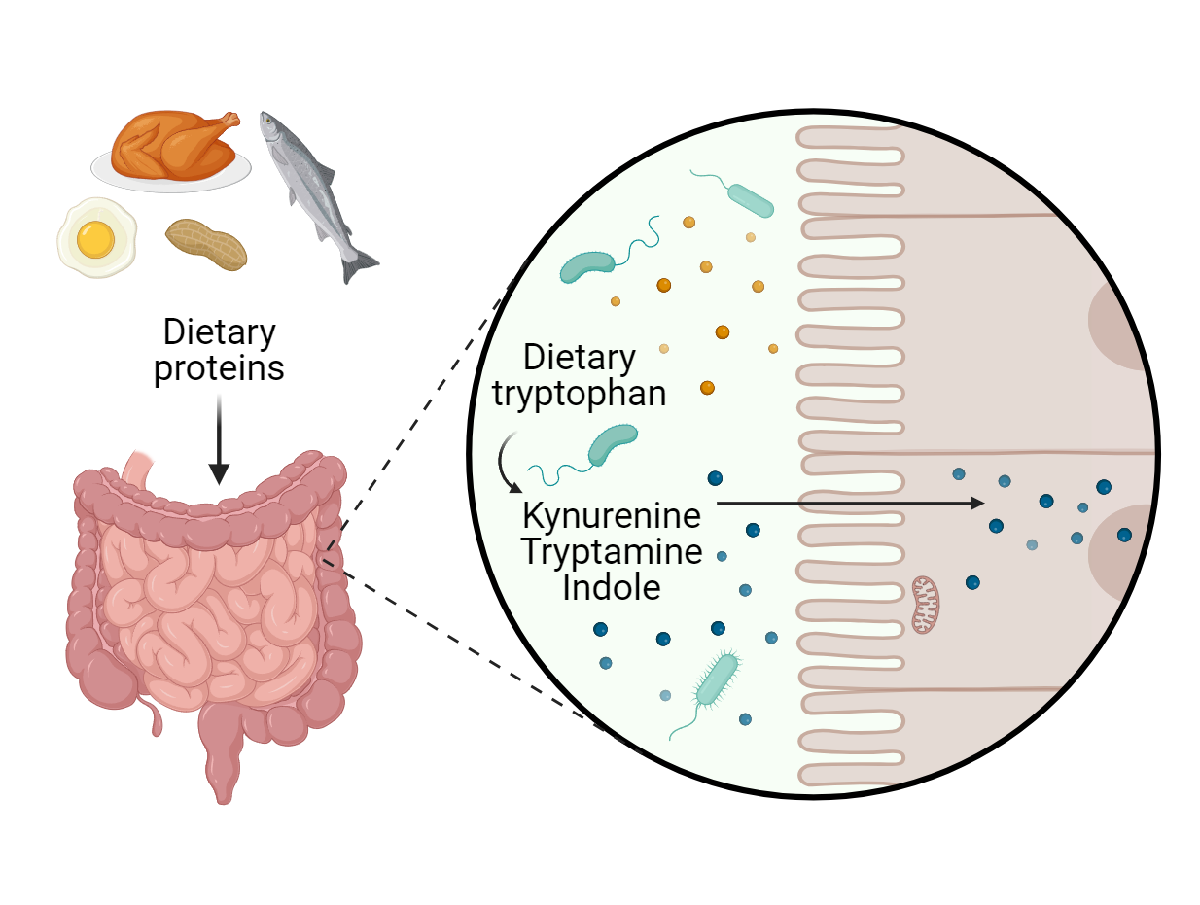

Lets investigate the impact of the microbiome on the maximum production of tryptophan. First we will load a germ-free WBM and constrain it with the Average European Diet. We choose the female WBM "Harvetta" as muWBM_CSM5MCXD_female.mat is a combination with a Harvetta WBM and a microbiome. If we were to use Harvey the comparison will not work, as changes could either be due to sex or the microbiome.

% Prepare a germ-free WBM model.
modelGF = loadPSCMfile('Harvetta');
modelGF = setDietConstraints(modelGF, 'EUAverageDiet');

Now we can add a demand reaction for tryptophan in the blood:

% Add demand reaction
modelGF = addDemandReaction(modelGF,'trp_L[bc]');
% Unconstrain dm reaction upper bound for further analysis
modelGF = changeRxnBounds(modelGF,'DM_trp_L[bc]',100000,'u');

First we will perform FBA on a reaction of interest in a germ-free WBM model:

% Set the objective function
modelGF = changeObjective(modelGF, 'DM_trp_L[bc]');
% Set objective function to maximise for the reaction
modelGF.osenseStr = 'max';
% Perform FBA
solution_GF = optimizeWBModel(modelGF);
% Check maximised flux through 'EX_trp_L[bc]' 
solution_GF.f

We see that the maximum flux for blood pool of L-tryptophan is 5.4520 mmol/day.

Now we will repeat the procedure for mWBM_CSM5MCXD_female.mat. The same steps we performed in example five.

% Add demand reaction
mWBMDemand = addDemandReaction(mWBM,'trp_L[bc]');

% Unconstrain dm reaction upper bound for further analysis
mWBMDemand = changeRxnBounds(mWBMDemand,'DM_trp_L[bc]',100000,'u');

% Change the objective function
mWBMDemand = changeObjective(mWBMDemand, 'DM_trp_L[bc]');

% Set objective function to maximise for the reaction
mWBMDemand.osenseStr = 'max';

% Perform FBA
solution_mWBM = optimizeWBModel(mWBMDemand);

% Check maximised flux through 'EX_tryp_L[bc]]' 
solution_mWBM.f

We see that again the value of 334 mmol/day is reached for mWBM_CSM5MCXD_female.mat. To see what the microbiome contribution, both direct and indirect is on the demand reaction of L-tryptophan in the blood we subtract the germ-free value from the human-microbiome value

solution_mWBM.f - solution_GF.f

And we see that the microbiome can maximally increase the blood pool of L-tryptophan by 329 mmol/day

## Part 3: Solving your models for multiple reactions

The code above has not been optimised for speed but rather for understanding what options are available and which steps are required to solve a HMmodel. We have developed a function that has been optimised for speed called optimiseRxnMultipleWBM. The function performs the same steps as discussed in the tutorial, but has been adjusted to take multiple objective functions and models. We will use this function to calculate a couple of reactions with the HM models generated Part 1: Setup and model creation. If you have not run this step or do not have the HMmodels, you can find them also in the supplementary materials. The reason we do not run more models and reactions is that it quickly becomes times consuming to optimise each objective function of all indicated models if either the amount of models or objective functions increase.

mWBMPath, solutionDir, rxnList, 'diet', , 'numWorkers', , 'saveFullRes', , 'paramFluxProcessing', , 'saveDir', , 'solver', solver

- mWBMPath- a directory where all the mWBMs you want to solve are stored

- **solutionDir** - a directory where you want the results to be saved

- **rxnList** - a cell array of reactions you want to solve. These can be existing reactions in the model or demand reactions not yet present in the WBM. If rxnList includes demand reactions, you have to use in "DM_" and the metabolite + comparment of interest. The code will recognise that that demand reaction is not yet in the model and add it the the model before solving for that reaction. The cell array can be a combination of existing reactions and metabolites you want a demand reaction added for.

- **diet** - a diet you want to be used on all the models. Default is EUAverageDiet

- **numWorkers** - Number of workers that will perform FBA in parallel. Note that more workers does not necessarily make the function faster. It is generally not recommended to set numWorkers equal to the number of available cores as linear solvers can already support multi-core linear optimisation, thus resulting in unnecessary overhead. On computers with 8 cores or less, it is recommended to set numWorkers to 1. On a computer with 36 cores, an optimal configuration of numWorkers=6 was found.

- **saveFullRes** - Boolean (true/false) indicating if the solution fields of fba = optimizeWBModel(model, ‘max), for the entire flux vector (fba.v), the metabolite shadow prices (fba.y), and the reaction reduced cost values (fba.w) are saved. If saveFullRes is set to true, the reaction IDs (model.rxns) and metabolite IDs (model.mets), are also saved.  

- **paramFluxProcessing** - Structured array with the fields

-             .**NumericalRounding** defines how much the predicted flux values are rounded. A defined value of 1e-6 means that a flux value of 2 + 2.3e-8 is rounded to 2.                 A flux value of 0 + 1e-15 would be rounded to exactly zero. This rounding factor will also be applied to the shadow price values. If microbiome relative abundance data is provided, the same rounding factor will be applied to the relative abundance data .RxnRemovalCutoff defines the minimal number of samples for which a                     unique reaction flux could be obtained, before removing the reaction for further analysis. This parameter can be expressed as 1) * fraction:  the fraction of samples with unique values, 2) * SD: the standard deviation across samples, and 3) * count: the counted number of unique values. If microbiome relative abundance data is provided, the same removal cutoff factor will be applied to the relative abundance data.Defaults to: {'fraction',0.1}

-             .**RxnEquivalenceThreshold** defines the minimal threshold of when functionally identical flux values are predicted, and are thus part of the same linear pathways. The threshold for functional equivalence is expressed as the R2 (r-squared) value after performing a simple linear regression between two reactions.                     Default to: 0.999.

-             .**fluxMicrobeCorrelationType** defines the method for correlating the predicted fluxes with microbial relative abundances. Note that this metric is not used if muWBMs are not present. The available correlation types are: 1) * regression_r2:  the R2 (r-squared) value from pairwised linear regression on the predicted fluxes against microbial relative abundances. 2) * spearman_rho: the correlation coefficient, rho obtained from pairwise Spearman nonparametric correlations between predicted fluxes and microbial relative abundances. Default to: 'regression_r2'.

- **saveDir** - Character array with path to directory where the flux processing results will be saved.

- **solver** - solver used to perform optimisations. We defined this already at the start of the tutorial.

In this tutorial we are going to solve for the demand of D-glucose, butyrate, lithocholate and L-glutamate in the blood compartment as well as the ATP demand in the cytosol of the Brain. Butyrate, litocholate and L-glutamate are investigated as they are often found the be changed between controls and Parkinon's disease (PD)patients in unpublished work. D-glucose is a metabolite that has been shown to not show signifcant alterations in unpublished work. ATP demand in the brain is chosen as we are interested if there is a difference in PD brain energy consumption. We included 5 demand reactions, that are not yet present in the model ('DM_glc_D[bc]', 'DM_but[bc]', 'DM_glu_L[bc]', 'DM_HC02191[bc]'). The function will automatically add on demand reactions that are not yet present in the model. However, we have to input the reaction ID as it would be expected by the model. This procedure is easily done by setting DM_ before the metabolite for which the demand reaction has the created. Don't forget compartment indications and organ prefix where required!

We now set all the variables required to run *analyseWBMs.m*, the path variables we already created at the start of the tutorial and we will now store them in the variables used for the function. 

% Predefined at the start
% Set paths
resultPath = '';
% Path to mWBMs
mWBMPath = fullfile(resultPath,'mWBMmodels'); 
% Output path for the flux results
fluxPath = fullfile(resultPath,'resultFlux');
% Output path for the flux descriptions
fluxAnalysisPath = fullfile(resultPath,'resultFlux', 'fluxAnalysis'); 

% Set which reactions have to be optimised for
rxnList = {'DM_glc_D[bc]';
    'DM_but[bc]'}
%     'DM_glu_L[bc]';
%     'DM_HC02191[bc]';
%     'Brain_DM_atp_c_'};

% Use the same diet as when you created the mWBMs. Otherwise change
% EUAverageDiet to the diet you used in creating the mWBMs.
diet = 'EUAverageDiet';

 By default, the analyseWBMs function will save the following FBA outputs: 

- .f                            1 by n vector with the predicted flux value in mmol/day/person through the objective reaction

- .rxns:                     1 by n cell array with the reaction IDs for each predicted flux

- .ID                         Cell with sample ID

- .sex                       Cell with sex information 

- .stat                       1 by n vector with the FBA statistics

- .origStat                 1 by n vector with the original FBA solution statistic from solver

- .taxonNames         o by 1 cell array with the names of taxa in the WBM (Only when applicable)

- .relAbundances      o by 1 vector with the relative abundances of all taxa in the WBMs

- .shadowPriceBIO   o by n vector with the shadow price values of the pan taxon biomass metabolite

Additionally, the following outputs can be added to the FBA result structure by setting saveFullRes to true

- .v                           m by n array with the flux vectors of all reactions in the WBM m for each of the optimised reactions n.

- .y                           p by n array with the metabolite shadow prices of all metabolites in the WBM m towards each each the optimised reactions n.

- .w                          m by n array with the reduced cost values of all reactions in the WBM m for each of the optimised reactions n.

- .modelRxns           m by 1 cell array with all reaction IDs in the WBM.

- .modelMets           p by 1 cell array with all metabolite IDs in the WBM.

- .modelUB              m by 1 vector with all upper bounds on the reactions in the WBM.

- .modelLB               m by 1 vector with all lower bounds on the reactions in the WBM.

For this tutorial, we will  save the additional metrics. Note that the additional metrics take up a lot of hard drive space.

% We are not generating big solution files so it can be set to true.
saveFullRes = true;

Next, we will set the number of Matlab workers used for optimisation of the WBMs in the mWBMPath.

numWorkersOptimization = 1;

It is generally not recommended to set numWorkers equal to the number of available cores as linear solvers can already support multi-core linear optimisation, thus resulting in unnecessary overhead. On computers with 8 cores or less, it is recommended to set numWorkers to 1. On high core count machines, a numWorker value between 10% and 20% of the number of available cores is recommended. 

Finally, we will set parameters for how the flux results are processed and prepared for statistical analysis:

% Define structure for parameters
paramFluxProcessing = struct;

% Define the rounding factor of the FBA results
paramFluxProcessing.numericalRounding = 1e-6; 

% Define when a reaction is removed for further statistical analysis. Here,
% a reaction is set to be removed if the 10% or more of the flux results
% are unique values. For small sample sizes, it is recommended to set this
% value to 0.
paramFluxProcessing.rxnRemovalCutoff = {'fraction',0.1};

% Define how the predicted fluxes will be correlated against the microbial
% relative abundances. Here, we chose to perform a spearman rank
% correlations, but simple linear regressions are also supported.
paramFluxProcessing.fluxMicrobeCorrelationType = {'spearman_rho'};

% We set these to their default values. If you want you can play around
% with the settings and see how that changes the processed results you
% obtain
paramFluxProcessing.NumericalRounding = {'fraction',0.1};
paramFluxProcessing.RxnEquivalenceThreshold = 0.999;
paramFluxProcessing.fluxMicrobeCorrelationType = 'regression_r2';

Running *analyzeWBMs.m* will also create and solve germ free WBMs. The germ free WBMs are made by taking one male and one female mWBM and setting the microbiome biomass exchange and metabolite transports to 0. This ensure the microbiome cannot interact with the WBM anymore. For miWBMs, a germ free model for each miWBM. These germ-free models can serve baseline of what the model is capable of doing without the microbiome. When we would compare the germfree results against the mWBM results we get an indication of the microbial contribution to that specific reaction/metabolite. 

Now that everything is defined, we can press Run Section from the Live Editor.

% Call on the function
analyseWBMs(mWBMPath, paths.fba.outputPathFluxAnalysis, rxnList, 'numWorkers',...
    numWorkersOptimisation, 'saveFullRes', saveFullRes, 'paramFluxProcessing', ...
    paramFluxProcessing, 'fluxAnalysisPath', fluxAnalysisPath, 'solver', solver);

After isolating the microbial component of the predicted fluxes, reactions that have a flux value of 0, i.e., reactions without a net influence of the gut microbiome, in over a user defined threshold percentage of samples (default = 90% ) are removed from analysis . Reactions having less than  user defined threshold percentage of unique values against the sample size, are also removed from analysis. These reactions are removed to ensure an adequate samples size for later statistical analysis. Samples without a net microbial contribution can artificially skew statistical results, thus potentially masking any statistical associations with a feature of interest. Next, the reaction fluxes are checked to be linearly dependent. Linear dependence between flux predictions can occur when metabolites are in the same pathway come from identical microbial sources. Linear dependence was tested by performing spearman correlations. Reactions with fluxes that have spearman correlation coefficients above the user defined threshold (Default rho = 0.999), are flagged as linearly dependent. Linearly dependent metabolic fluxes were collapsed into a new variable as including them both does not add new information.The final table contains the microbial component of theobtained fluxes, where reactions that are mostly 0 or have limited unique flux values over samples are removed. Microbiome contributions to flux values that are highly correlated to each other are also removed and grouped into a single variable. The table is saved as flux_results.xlsx

We also obtain which pan-species in the WBMs can contribute to the flux value for a reaction. The function extracts the shadow prices of the pan-species biomass compounds, which is saved as "shadowPricesBio" in the .mat solution structure. Each solution .mat file is structured where each column is a reaction we wanted to be solved and the rows are the pan-species models present in that specific microbiome, stored in "speciesBIO". Each cell is the shadowprice for the respective pan-species biomass metabolite and the respective solved reaction. But what is a shadow price? In its basis it is the change in consumption/production of a metabolite that will increase the flux through the target reaction by 1mmol/day. In the context of biomass of pan-species models in the microbiome, we can interpret that as follows. If the shadowprice is -5 for species A, it means that if the biomass production of species A is increased by 5 mmol/day the flux through the reaction will be increased by 1mmol/day. If the shadowprice is 5 for species B, it means that if the biomass production of species B is increased by 5mmol/day the flux through the reaction will be decreased by 1 mmol/day. The closer the is shadowprice to 0, the smaller is the required change in metabolite consumption/production to enact a change of 1mmol/day on a reaction This means that metabolites with shadow prices closer to 0 have a larger impact on the flux of a reaction than larger shadow prices. The shadow prices are stored as a summary file in shadowPriceStatistics.xlsx and for each individual reaction the raw information is saved in the folder microbeShadowPrices in the fluxAnalysis folder.

Then, the function correlates the relative abundances (as calculated per MARS, Part 1 of this tutorial) of individual microbes to the microbial flux contributions, as we know which microbe models are contributing to which flux from the shadowPrices. By only correlating the relative abundances of microbes that affect the microbial flux we vastly reduce the number of correlations that are performed. The data is saved as microbe_metabolite_corr.csv.

Running analyseWBMs will also load and solve the germ-free WBMs alongside the mWBMs. These germ-free models can serve baseline of what the model is capable of doing without the microbiome. When we would compare the germ-free results against the mWBM results, we get an indication of the microbial contribution to that specific reaction. 

All results are stored in a table in the "fluxPath" folder, flux_results.xlsx. 

## Statistical analysis of the flux results

Next, we will perform an exploratory analysis on the flux results. 

The type of statistical analysis to be performed is dependent on the nature of the response variable and on the confounder variables. The table below shows the type of statistical analyses performed for each combination of input variables for the response and confounder variables.

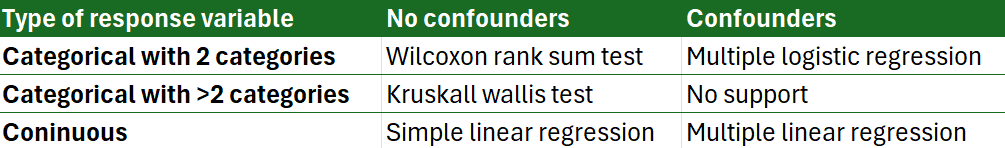

Table 1. Types of analyses on the fluxes and microbial relative abundances supported by the performStatsPersephone.m function. 

Before performing the statistical analysis, the predicted fluxes are log2 transformed and z-scaled. Z-transformation was done to ensure that the statistical effect sizes, e.g., odds ratio's and regression coefficients, are comparable across reactions. Not performing a z-transformation can result in dramatically different effect sizes as the scale of flux values can differ between reactions. Log transformation on the relative abundances was done to increase normality of the relative abundance distributions. If the WBMs contain a gut microbiota lumen, i.e, mWBMs or miWBMs, the extracted relative abundances from the WBMs are analysed in the exact same manner as the predicted fluxes. 

First, we will define the input paths:

outputPathStatistics = fullfile(resultPath,'resultStatistics');
processedFluxPath = fullfile(resultPath,'fluxAnalysis', 'processed_fluxes.csv');
wbmRelAbunPath = fullfile(resultPath,'fluxAnalysis', 'WBM_relative_abundances.csv');
metadataPath = fullfile(resultPath,'demo_metadata_processed.csv');

Next, we will read the metadata and we will choose a metadata variable to investigate.

metadata = readMetadataForPersephone(metadataPath);
head(metadata)

Here, we will set diagnosis as the response (dependent) variable for the statistical analysis. 

response = 'diagnosis';

% Assess the number of samples for each diagnosis group
[groupIndices,categories] = findgroups(metadata.diagnosis);
table(categories, histcounts(groupIndices)','VariableNames',...
    {'Diagnosis','Number of samples'})

Only three sample were non-IBD. These samples are removed and we will analyse differences between individuals with Crohn's disease (CD) with those that have ulcerative colitis (UC).

metadata(matches(metadata.diagnosis,'nonIBD'),:)=[];

% Save updated metadata file
updatedMetadataPath = erase(metadataPath,'.csv') + "_removedNonIBD.csv";
writetable(metadata,updatedMetadataPath);

Next, we will define variables to control for unwanted confounding effects.  We will use age and sex as control variables here.

confounders = {'age', 'Sex'};

As mWBMs were generated for this dataset, exploratory statistics against the response variable will also be generated for the microbial relative abundances. We will however, only analyse microbial species that are present in at least an X percentage of samples in the cohort. Here, we will define this cutoff value as 10% of samples.

microbeCutoff = 0.1;

After setting this cutoff, we can now perform the statistical analysis as follows:

% Run statistics pipeline
% We recommend that you copy and paste this and run it in the command
% window because there can be a long output which is prone to cause issues
% in live scripts.
results = performStatsPersephone(outputPathStatistics, processedFluxPath, ...
    updatedMetadataPath, response, 'pathToWbmRelAbundances', wbmRelAbunPath, ...
    'confounders',confounders,'microbeCutoff',microbeCutoff);

If no microbiome data was available, this function can be run as follows:

% Run statistics pipeline
results = performStatsPersephone(outputPathStatistics, processedFluxPath, ...
    updatedMetadataPath, response, 'confounders',confounders);

To summarise, these variables are required for statistical analysis: 

Required variables

- outputPathStatistics - The path to the file with the processed fluxes. This file should be found in the following path YOUR WORKING DIRECTORY / results / `processed_fluxes_Thr_"YOUR_THRESHOLD".csv. `

- wbmRelAbunPath - The path to the relative abundance file used to generate microbiome models. This is an output from MARS. If the tutorial was followed it should be in a default location. Otherwise define the location where the file can be found

- metadataPath - The path to the metadata file.

- response - Name of the splitting variable in a case/control study or the name of a continuous variable of interest to associate against. 

The following variables are optional:

- confounder variables - Names of variables to control for when analysing the flux results. Default = empty cell array.

- microbeCutoff - Cutoff value for which microbes to analyse.

After running performStatsPersephone, all results are saved in "`statistical_results.xlsx".`

This is the end of the tutorial. 

References

[1] Thiele, I., Sahoo, S., Heinken, A., Hertel, J., Heirendt, L., Aurich, M. K., & Fleming, R. M. (2020). Personalized whole‐body models  integrate metabolism, physiology, and the gut microbiome. *Molecular systems biology*, *16*(5), e8982.